## Modelo de Robot (3 DOF)

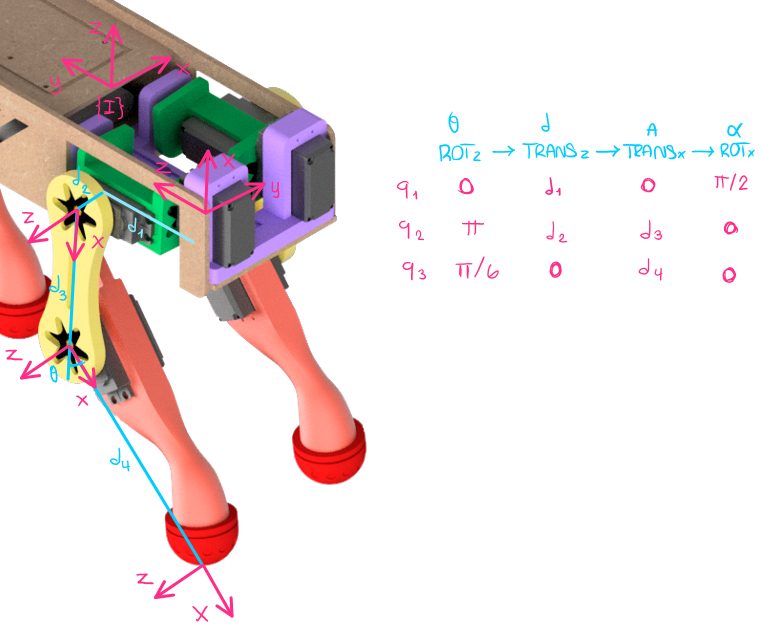

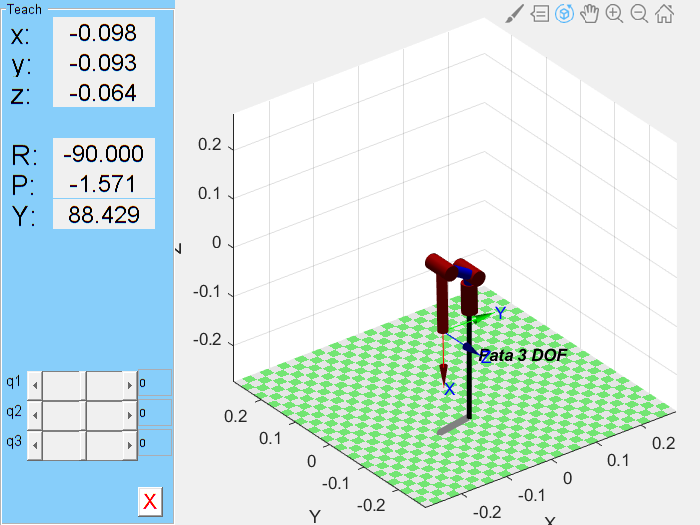

% Dimensiones del robot
d1 = 5/100;
d2 = 1.5/100;
d3 = 8/100;
d4 = 129/1000;

ConfigInicial = 'Sentado';

% Definición de matriz de Denavit-Hartenberg
switch ConfigInicial
    % Posición 0 como en imagen arriba
    case 'Imagen'
        L1 = Revolute('offset', 0,   'd', d1, 'a',  0, 'alpha', pi/2);
        L2 = Revolute('offset', pi,  'd', d2, 'a', d3, 'alpha', 0);
        L3 = Revolute('offset', pi/6,'d',  0, 'a', d4, 'alpha', 0);
    
    % Posición 0 con robot sentado o "echado"
    case 'Sentado'
        L1 = Revolute('offset', 0,      'd', d1, 'a',  0, 'alpha', pi/2);
        L2 = Revolute('offset', pi-pi/6,'d', d2, 'a', d3, 'alpha', 0);
        L3 = Revolute('offset', 4*pi/6, 'd',  0, 'a', d4, 'alpha', 0);

    % Posición 0 con robot parado
    case 'Parado'
        L1 = Revolute('offset', 0,      'd', d1, 'a',  0, 'alpha', pi/2);
        L2 = Revolute('offset', pi-pi/6,'d', d2, 'a', d3, 'alpha', 0);
        L3 = Revolute('offset', pi/3,   'd',  0, 'a', d4, 'alpha', 0);
end

% Definimos el robot como un objeto SerialLink
Pata3DOF = SerialLink([L1 L2 L3], 'name', 'Pata 3 DOF');

% Transformación de base para pata delantera izquierda (Pata analizada 
% en imagen). No estoy seguro porque la transformación de base no se 
% refleja en la gráfica del "teach".
OffsetY = 78.55/1000;
OffsetX = 28.431/1000;
OffsetZ = 25.104/1000;
IT_B_3DOF = transl(-OffsetX, -OffsetY, -OffsetZ) * trotx(-pi/2) * trotz(-pi/2);
Pata3DOF.base = IT_B_3DOF;

% Visualización y manipulación de la pata
Pata3DOF.teach();

## Modelo de Robot (2 DOF)

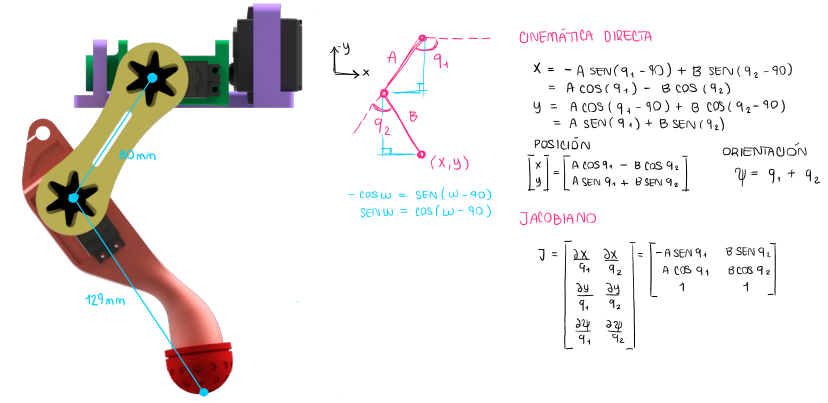

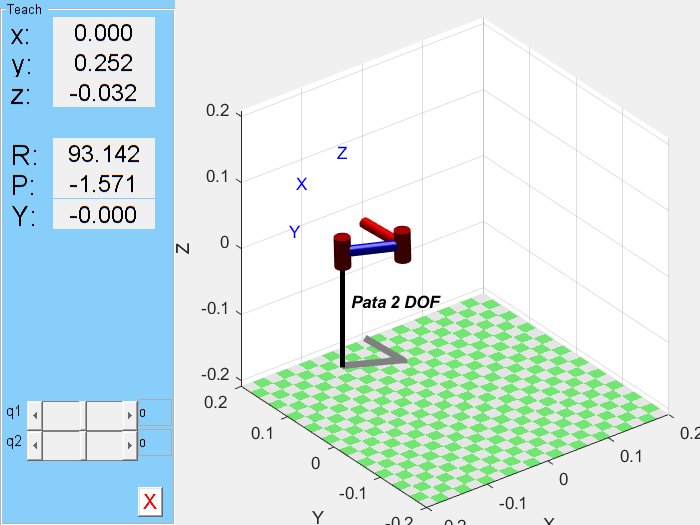

% Dimensiones pata
A = 8/100;
B = 129/1000;

% Definición de matriz de Denavit-Hartenberg
L1 = Revolute('offset', -pi/6,'d', 0, 'a', A, 'alpha', 0);
L2 = Revolute('offset', 4*pi/6, 'd', 0, 'a', B, 'alpha', 0);

% Definimos el robot como un objeto SerialLink
Pata2DOF = SerialLink([L1 L2], 'name', 'Pata 2 DOF');

% Transformación de base para pata trasera izquierda (Visto desde frente).
OffsetY = 158.85/1000;
OffsetX = 64.031/1000;
OffsetZ = 34.054/1000;
IT_B_2DOF = transl(-OffsetX, OffsetY, -OffsetZ) * troty(-pi/2) * trotz(pi);
Pata2DOF.base = IT_B_2DOF;

% Visualización y manipulación de la pata
Pata2DOF.teach();

## Trayectoria Pata 3 DOF

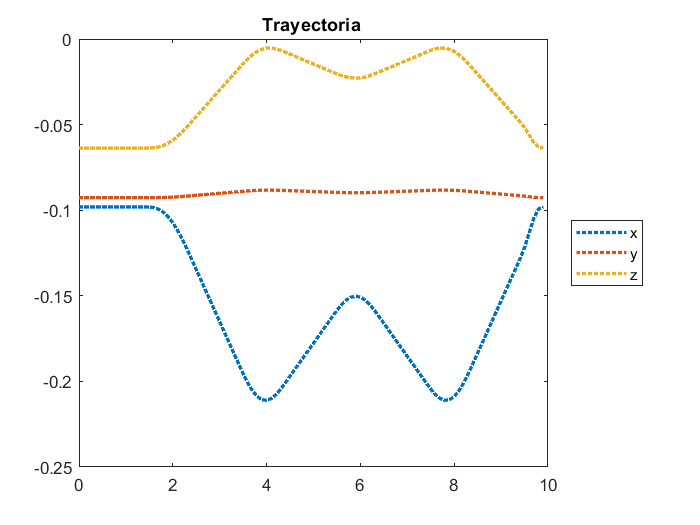

% Configuración inicial
q0 = zeros(3,1);

% Se obtiene la pose de la pata
To = cuadFK(q0, 3, IT_B_3DOF, eye(4));

% Posiciones "clave"                  
PataPosInicial = To(1:3, 4);                        % Posición de pata "sentada"
PataPosParada = [-0.220 -0.088 -0.002];             % Posición de pata "parada"
PataPosArriba = [-0.143 -0.09 -0.025];              % Posición de pata "levantando el pie"

% Via o sucesión de puntos "clave" a seguir
Via = [PataPosInicial'; PataPosParada; PataPosArriba; PataPosParada; PataPosInicial'];

% Creación de la trayectoria. Los parámetros de la función son los
% siguientes:
%   - Via = Puntos a seguir. Cada punto es una fila de la matriz.
%   - 1 = Velocidades máximas en un eje específico. 1 para todos.
%   - [] = Tiempo entre cada uno de los puntos "k" de la trayectoria.
%   - Efector_PosInicial' = Posición desde la que inicia a trayectoria.
%   - 0.1 = Time step
%   - 1 = Tiempo empleado en la aceleración para llegar al valor nominal.
Trayectoria = mstraj(Via, 1, [], PataPosInicial', 0.1, 1);

% Settings de graficación
figure(1); figure('visible','on');

% Se grafica el punto inicial
plot3(PataPosInicial(1), PataPosInicial(2), PataPosInicial(3), 'o');

% Se grafica la trayectoria a seguir
hold on;
plot3(Trayectoria(:,1),Trayectoria(:,2), Trayectoria(:,3));

% Cinemática inversa para cada punto en "Trayectoria". Recordar que cada
% punto se encuentra en una nueva fila.
q_old = q0;
Q = zeros(size(q0,1), size(Trayectoria,1));
for i = 1:size(Trayectoria,1)
    Punto = Trayectoria(i,:);                           % Se extrae la fila "i" o el punto "i"    
    T = transl(Punto(1), Punto(2), Punto(3));           % Matriz de traslación (4x4) a partir de punto "i"
    q_new = cuadIK(T, q_old, 3, IT_B_3DOF, eye(4),1);   % Configuración a partir de la pose deseada. El 1 es para "solo posicion"
    q_old = q_new;
    Q(:,i) = q_new;
end

Pata3DOF.plot(Q');     

T=10;
tau = 0:0.1:T;
tau=tau(1:100);
close all
plot(tau,Trayectoria(:,1),':',tau,Trayectoria(:,2),':',tau,Trayectoria(:,3),':','LineWidth',2)
%hold on
%plot(tau,Trayectoria(:,2),':','LineWidth',2)
%plot(tau,Trayectoria(:,3),':','LineWidth',2)
title('Trayectoria ')

leg = {'x','y','z'};
legend(leg{:},'location','eastoutside')

## Trayectoria Pata 2 DOF

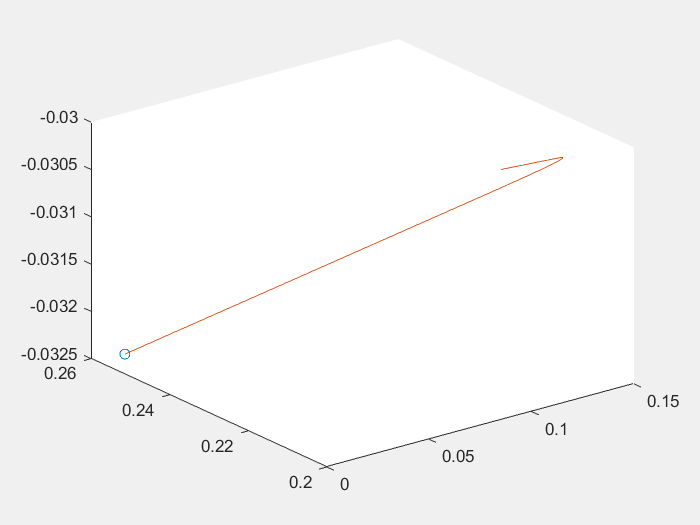

% Configuración inicial
q0 = zeros(2,1);

% Se obtiene la pose de la pata
To = cuadFK(q0, 2, IT_B_2DOF, eye(4));

% Posiciones "clave"                  
PataPosInicial = To(1:3, 4);                    % Posición de pata "sentada"
PataPosParada = [0.128 0.203 -0.03];            % Posición de pata "parada"
PataPosArriba = [0.091 0.205 -0.03];            % Posición de pata "levantando el pie"

% Via o sucesión de puntos "clave" a seguir
Via = [PataPosInicial'; PataPosParada; PataPosArriba; PataPosParada; PataPosInicial'];

% Creación de la trayectoria. Los parámetros de la función son los
% siguientes:
%   - Via = Puntos a seguir. Cada punto es una fila de la matriz.
%   - 1 = Velocidades máximas en un eje específico. 1 para todos.
%   - [] = Tiempo entre cada uno de los puntos "k" de la trayectoria.
%   - Efector_PosInicial' = Posición desde la que inicia a trayectoria.
%   - 0.1 = Time step
%   - 1 = Tiempo empleado en la aceleración para llegar al valor nominal.
Trayectoria = mstraj(Via, 1, [], PataPosInicial', 0.1, 1);

% Settings de graficación
figure(1); figure('visible','on');

% Se grafica el punto inicial
plot3(PataPosInicial(1), PataPosInicial(2), PataPosInicial(3), 'o');

% Se grafica la trayectoria a seguir
hold on;
plot3(Trayectoria(:,1),Trayectoria(:,2), Trayectoria(:,3));


% Cinemática inversa para cada punto en "Trayectoria". Recordar que cada
% punto se encuentra en una nueva fila.
q_old = q0;
Q = zeros(size(q0,1), size(Trayectoria,1));
for i = 1:size(Trayectoria,1)
    Punto = Trayectoria(i,:);                           % Se extrae la fila "i" o el punto "i"    
    T = transl(Punto(1), Punto(2), Punto(3));           % Matriz de traslación (4x4) a partir de punto "i"
    q_new = cuadIK(T, q_old, 2, IT_B_2DOF, eye(4),1);   % Configuración a partir de la pose deseada. El 1 es para "solo posicion"
    q_old = q_new;
    Q(:,i) = q_new;
end

% Visualizando el movimiento de la pata
%Pata2DOF.plot(Q');



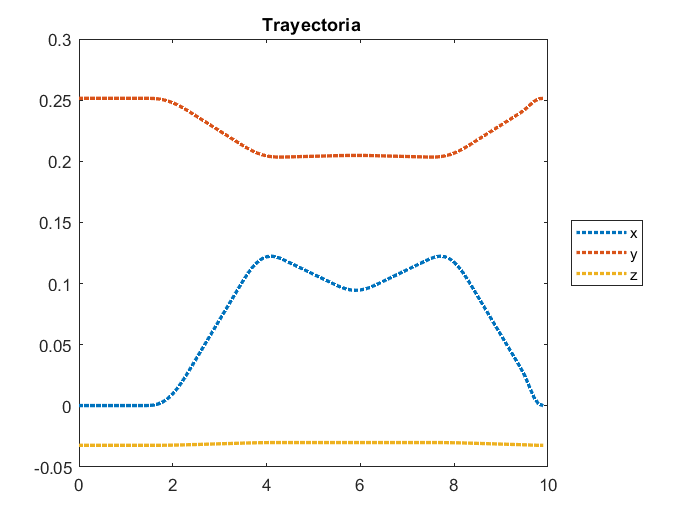



Pata2DOF.plot(Q');
T=10;
tau = 0:0.1:T;
tau=tau(1:100);
close all
plot(tau,Trayectoria(:,1),':',tau,Trayectoria(:,2),':',tau,Trayectoria(:,3),':','LineWidth',2)
title('Trayectoria ')

leg = {'x','y','z'};
legend(leg{:},'location','eastoutside')

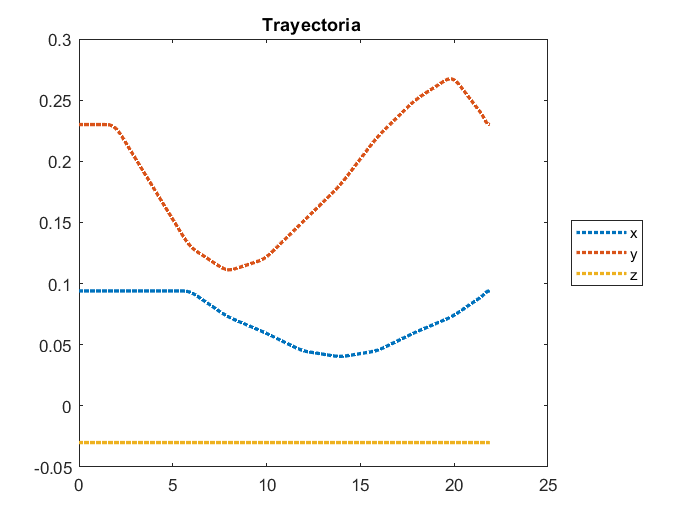

load('Traj.mat');
T=22;
tau = 0:0.1:T;
tau=tau(1:220);
close all
plot(tau,Trayectoria(:,1),':',tau,Trayectoria(:,2),':',tau,Trayectoria(:,3),':','LineWidth',2)
title('Trayectoria ')

leg = {'x','y','z'};
legend(leg{:},'location','eastoutside')

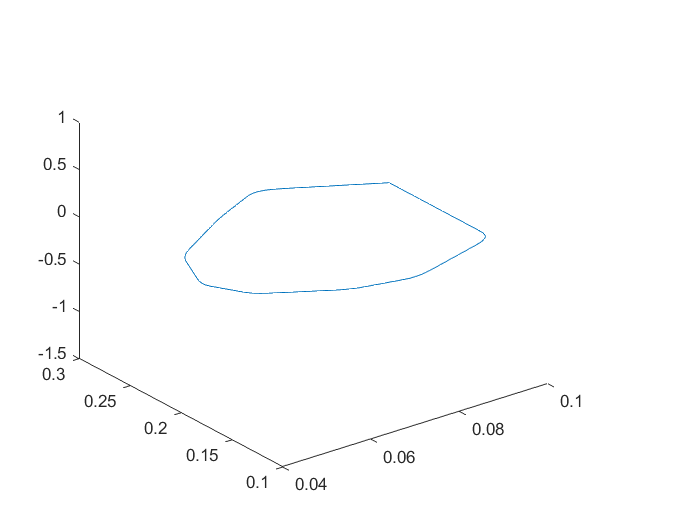


plot3(Trayectoria(:,1),Trayectoria(:,2), Trayectoria(:,3));